Name: Mukesh Aryal

Student ID: 268456

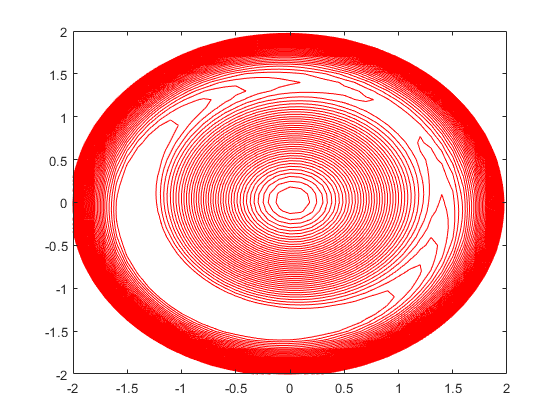

pobj=VideoWriter('contour','MPEG-4');
open(pobj)
[X,Y]=meshgrid(-2:0.1:2);
for m = 0.5:0.05:10
    Z=X+Y+0.5.*m.*(X.^2+Y.^2-2).^2;
    contour(X, Y, Z,0:0.5:20, 'Color', 'r');    
    frame = getframe;
    writeVideo(pobj, frame);
    
end

close(pobj)